# **Taller 13 14 15 Péndulo simple con fuerza tangencial**

Autor: Estefanía Citelly Guzmán

Fecha: 11/5/2023

## **Introducción**

El objetivo de este taller es resolver numéricamente, aplicando el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado no lineal de un péndulo simple con fuerza tangencial (ver sección 7.3.1 del texto guía) en un archivo Live Script de MATLAB e interpretar los resultados cambiando diversos parámetros a partir de la respuesta temporal y retrato de fase.

Para ello, resolveremos 10 puntos: En el primero se resolverá numéricamente la ecuación diferencial no lineal con condiciones iniciales para la velocidad y desplazamiento angular igual a 0 y graficaremos las soluciones temporales con una entrada o fuerza externa u = 1 y se analizará para qué valor máximo de la entrada el sistema rotará indefinidamente. 

En el segundo se graficará la curva de linealidad para observar el valor en el que se estabiliza el péndulo en función del valor de la entrada.

Para el tercer punto, se llevará a cabo la construcción del retrato de fase al variar la condición inicial de la velocidad angular, abarcando un rango de 3 a 6 radianes por segundo con incrementos de 0.5 radianes por segundo. Posteriormente, se procederá a interpretar los resultados obtenidos. Además, se busca identificar la frecuencia angular inicial que ocasiona una vuelta completa del péndulo, así como aquella que provoca tres vueltas consecutivas.

En el cuarto punto, se llevará a cabo una nueva representación gráfica del retrato de fase, esta vez variando la condición inicial de la posición angular en un rango de -6 a 6 radianes con incrementos de 0.5 radianes.

En los puntos 5, 6 y 7, se analizará el impacto que tiene la variación de la longitud, la masa y la fricción viscosa en el desplazamiento angular (θ) del péndulo, manteniendo una fuerza externa constante u= 1 y condiciones iniciales nulas.

En el octavo punto, abordaremos la obtención de la ecuación de estado y su posterior transformación a una ecuación diferencial homogénea con coeficientes constantes. Este análisis se llevará a cabo considerando un escenario de movimiento libre no amortiguado f = 0, u = 0, y partiendo de una posición angular inicial que sea menor a aproximadamente 0.5 radianes. Para simplificar el proceso, utilizaremos la aproximación lineal del seno del ángulo en radianes por el propio ángulo.

En el punto 9 exploraremos el procedimiento para determinar de manera aproximada los valores de f (coeficiente de fricción viscosa) y m (masa del péndulo), dados conocimientos sobre la respuesta temporal de un péndulo con una fuerza externa de 1 N, una longitud de 2 metros y una aceleración debido a la gravedad de 9.8 m/s². Este método se basará en un enfoque de tanteo.

Finalmente, en el último punto se llevará a cabo un experimento utilizando un péndulo. El cual se iniciará desde un ángulo inicial que oscilará entre 20 y 60 grados, y hallaremos los parámetros l y f si se conocen m y g.

## Metodología

Emplearemos un enfoque analítico para abordar el problema, utilizando un modelo no lineal que describe el comportamiento de un péndulo simple sujeto a una fuerza tangencial. El desarrollo del taller se llevará a cabo en un periodo de tres semanas,  en donde hallaremos su solución numéricamente utilizando el método de Runge-Kutta a través del comando ode45 en MATLAB. A partir de los resultados obtenidos, generaremos las respectivas gráficas y posteriormente analizaremos el comportamiento del sistema cuando modificamos distintos parámetros. Esto se llevará a cabo a través del estudio de la respuesta temporal y el retrato de fase del péndulo.

**Modelo matemático:**

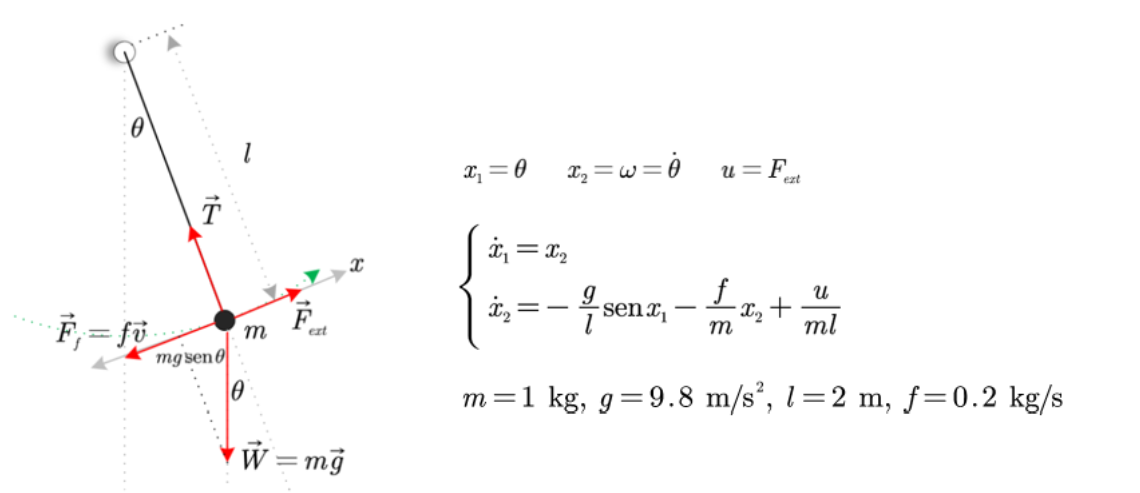

Donde, θ es el ángulo (en radianes, rad) respecto a la posición vertical, ω es la velocidad angular (en radianes por segundo, rad/s) y *u* es la fuerza externa aplicada tangencialmente. Los parámetros son la masa (*m*, en kilogramos), la longitud (*l*, en metros), la aceleración de la gravedad (*g*, en m/s2) y f es el coeficiente de fricción viscosa (*f*, N/(ms-1) o kg/s). Suposición: el hilo es rígido y tiene una masa que se puede despreciar, por lo que el péndulo puede tomar posiciones superiores.

## Resultados

## **punto 1**

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para qué valor máximo de la entrada el sistema rotará indefinidamente?

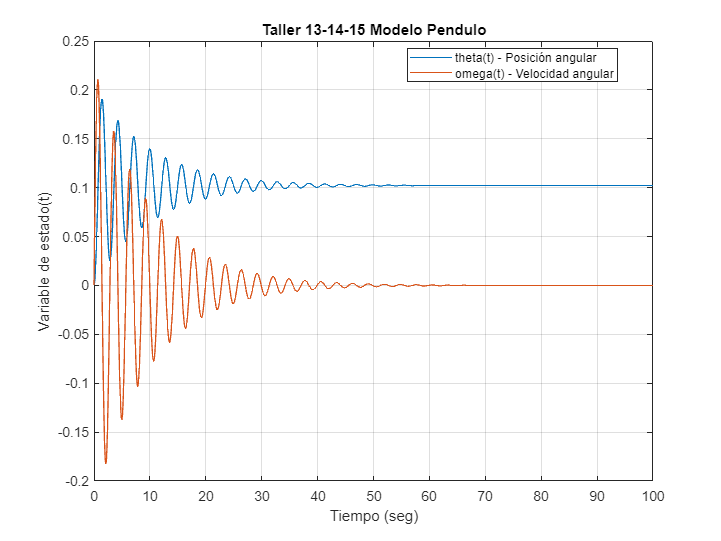

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
l = 2; %Longitud en metros
g = 9.8; %Aceleracion de la gravedad
F = 0.2; %Fricción viscosa   
U = 1; %Fuerza externa


% Creo las ecuaciones de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F/m)*x2 + (U/(m*l));
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);


% METODO NUMERICO
% Tiempo de muestreo: de 0.1 segundos
Ts = 0.1;
% Vamos a trabajar 1 minuto
tmin = 0;
tmax = 100;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;


% Defino condiciones iniciales:  desde el reposo con angulo cero y velocidad angular cero
Ci_x1 = 0;
Ci_x2 = 0;
% Como vamos a resolver numericamente armamos el vector de condiciones iniciales
Ci_pendulo = [Ci_x1 Ci_x2];


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t1,Sol1] =  ode45(Funciones_estado,tspan,Ci_pendulo);


% Punto 1 Simulamos
% Graficar la solucion
figure
plot(t1,Sol1)
grid on
xlabel('Tiempo (seg)')
ylabel ('Variable de estado(t)')
title('Taller 13-14-15 Modelo Pendulo')
legend({'theta(t) - Posición angular','omega(t) - Velocidad angular'}, 'Location', 'best')

## **punto 1 b**

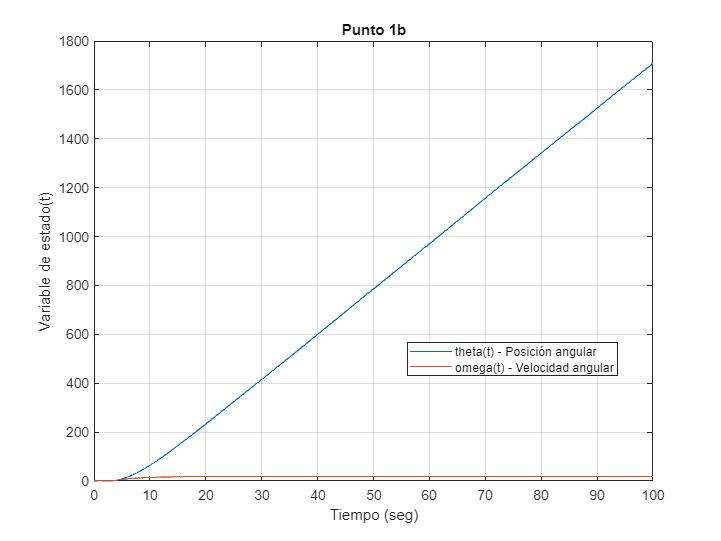

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
g = 9.8; %Aceleracion de la gravedad
l = 2; %Longitud en metros
F = 0.2; %Fricción viscosa    
U = 7.6; %Fuerza externa

% Creo las ecuaciones de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F/m)*x2 + (U/(m*l));
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);


% METODO NUMERICO
% Tiempo de muestreo: de 0.1 segundos
Ts = 0.1;
% definimos el tiempo maximo y el minimo
tmin = 0;
tmax = 100;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;


% Defino condiciones iniciales:  desde el reposo con angulo cero y velocidad angular cero
Ci_x1 = 0;
Ci_x2 = 0;
% Como vamos a resolver numericamente armamos el vector de condiciones iniciales
Ci_pendulo = [Ci_x1 Ci_x2];


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t1a,Sol1a] =  ode45(Funciones_estado,tspan,Ci_pendulo);


% Punto 1 Simulamos
% Graficar la solucion
figure
plot(t1a,Sol1a)
grid on
xlabel('Tiempo (seg)')
ylabel ('Variable de estado(t)')
title('Punto 1b')
legend({'theta(t) - Posición angular','omega(t) - Velocidad angular'}, 'Location', 'best')

## **Punto 2**

Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

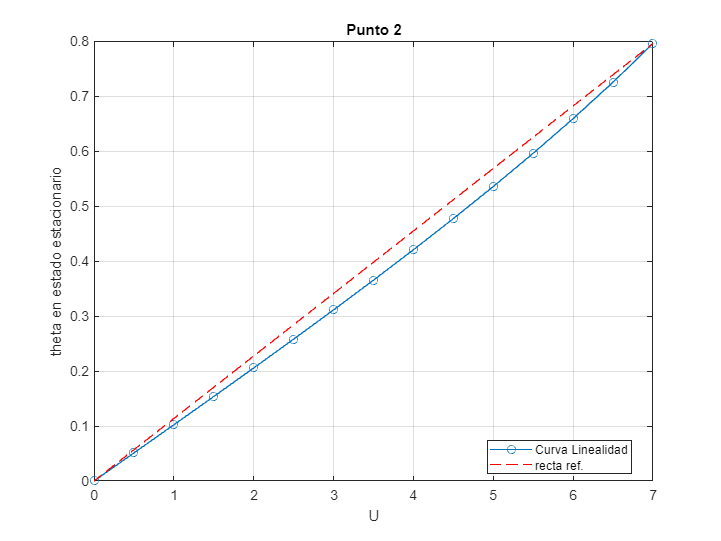

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
g = 9.8; %Aceleracion de la gravedad
l = 2; %Longitud en metros
F = 0.2; %Fricción viscosa    


% Creo la ecuacion de estado
Tasa_x1 = x2;
val_U = 0:0.5:7; %Fuerza externa


%Creamos el vector  de u
N = length (val_U);
%defino el rango de tiempo
tiempo = 0:0.1:100;

% Defino condicion inicial:  desde el reposo con angulo cero y velocidad angular cero
Ci = [0 0];
theta = [];

for i=1:N
    U = val_U(i);
% Creo la ecuacion de estado    
Tasa_x2 = -(g/l)*sin(x1) - (F/m)*x2 + U/(m*l);
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);

%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[~,Sol2] =  ode45(Funciones_estado,tiempo,Ci);
theta(i) = Sol2(end,1);
end

% Graficar la solucion
figure
plot(val_U,theta,'o-')
hold on
plot([0 val_U(end)], [0 theta(end)],'r--');
grid on

legend('Curva Linealidad','recta ref.', 'Location', 'best')
xlabel('U')
ylabel ('theta en estado estacionario')
title('Punto 2')

## **punto 3**

Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

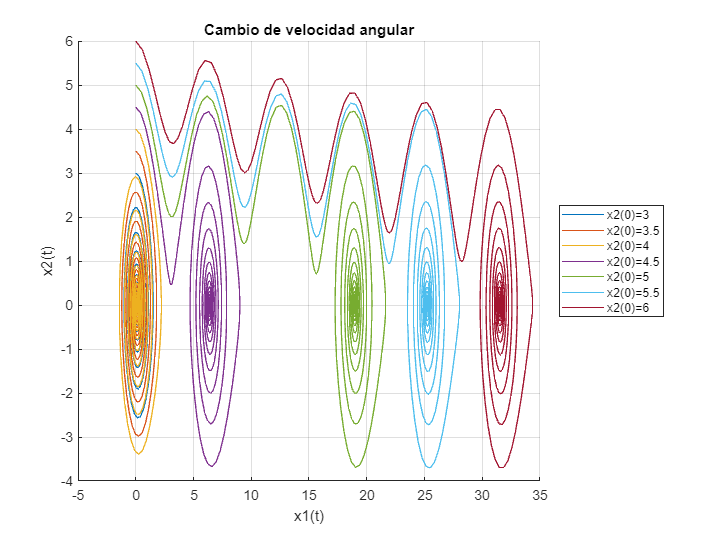

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
l = 2; %Longitud en metros
g = 9.8; %Aceleracion de la gravedad
F = 0.2; %Fricción viscosa    
U = 1; %Fuerza externa


% Creo las ecuaciones de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F/m)*x2 + (U/(m*l));
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);


% METODO NUMERICO
% Tiempo de muestreo: de 1 segundo
Ts = 0.1;
% Vamos a trabajar 1 minuto
tmin = 0;
tmax = 100;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;


% Defino condiciones iniciales:  
Ci_x1 = 0;
Ci_x2 =  3:0.5:6; %Valores a probar para la velocidad inicial


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45 y graficamos

figure
for i= 1:length(Ci_x2) % Vector para Ci_x2
    Ci_pendulo =  [Ci_x1 Ci_x2(i)]; % Armamos el vector de condiciones iniciales


[t,Sol3] = ode45(Funciones_estado,tspan,Ci_pendulo);
hold on
 plot(Sol3(:,1),Sol3(:,2))
 title('Cambio de velocidad angular')
xlabel('x1(t)')
ylabel ('x2(t)')
grid on
legend({'x2(0)=3','x2(0)=3.5','x2(0)=4','x2(0)=4.5','x2(0)=5','x2(0)=5.5' ,'x2(0)=6'},'Location','eastoutside')
end

## **punto 4**

Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

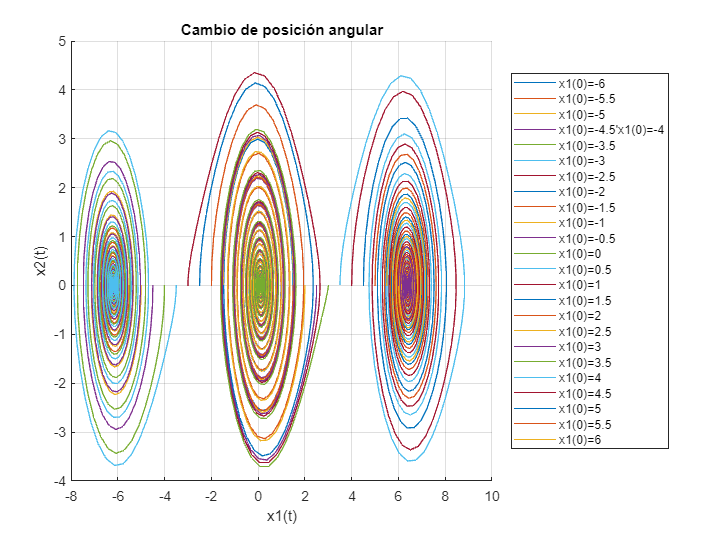

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
l = 2; %Longitud en metros
g = 9.8; %Aceleracion de la gravedad
F = 0.2; %Fricción viscosa    
U = 1; %Fuerza externa


% Creo las ecuaciones de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F/m)*x2 + (U/(m*l));
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);


% METODO NUMERICO
% Tiempo de muestreo: de 1 segundo
Ts = 0.1;
% Vamos a trabajar 1 minuto
tmin = 0;
tmax = 100;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;


% Defino condiciones iniciales:  
Ci_x1 = -6:0.5:6; %Valores a probar para la posición inicial
Ci_x2 = 0;


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45 y graficamos

figure
for i= 1:length(Ci_x1) % Vector para Ci_x1
    Ci_pendulo =  [Ci_x1(i) Ci_x2]; % Armamos el vector de condiciones iniciales


[t,Sol4] = ode45(Funciones_estado,tspan,Ci_pendulo);
hold on
 plot(Sol4(:,1),Sol4(:,2))
 title('Cambio de posición angular')
xlabel('x1(t)')
ylabel ('x2(t)')
grid on
legend({'x1(0)=-6','x1(0)=-5.5','x1(0)=-5','x1(0)=-4.5''x1(0)=-4', 'x1(0)=-3.5','x1(0)=-3','x1(0)=-2.5','x1(0)=-2','x1(0)=-1.5','x1(0)=-1','x1(0)=-0.5','x1(0)=0','x1(0)=0.5','x1(0)=1','x1(0)=1.5','x1(0)=2','x1(0)=2.5','x1(0)=3','x1(0)=3.5','x1(0)=4','x1(0)=4.5','x1(0)=5','x1(0)=5.5' ,'x1(0)=6'},'Location','eastoutside')
end

## **Punto 5**

- Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

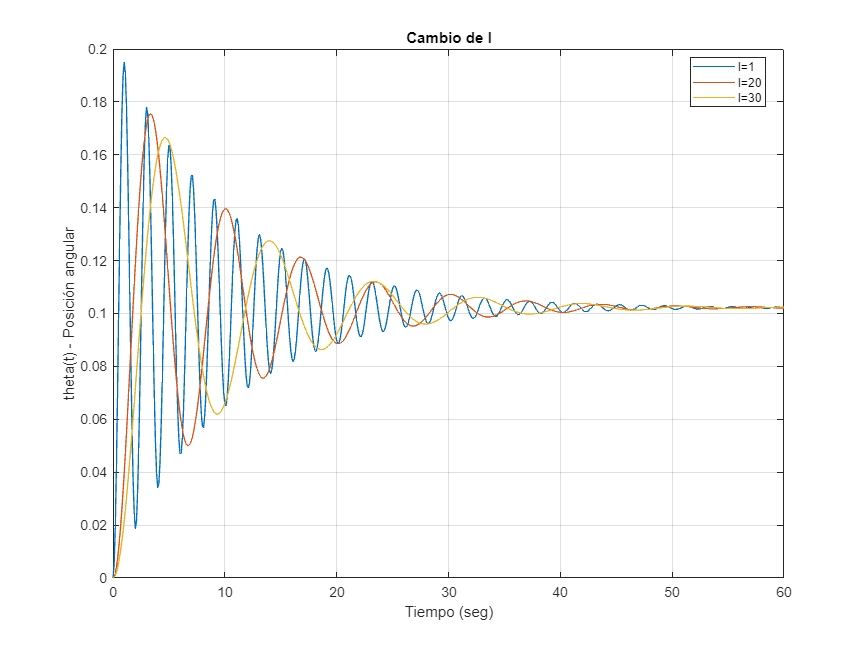

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
g = 9.8; %Aceleracion de la gravedad
l = 1:10:30; %Longitud en metros
F = 0.2; %Fricción viscosa   
U = 1; %Fuerza externa

% Creo las ecuacion de estado para la tasa x1
Tasa_x1 = x2;

% Defino condiciones iniciales:  desde el reposo con angulo cero y velocidad angular cero
Ci_x1 = 0;
Ci_x2 = 0;
% Como vamos a resolver numericamente armamos el vector de condiciones iniciales
Ci = [Ci_x1 Ci_x2];

% Tiempo de muestreo: de 0.1 segundos
Ts = 0.1;
% definimos el tiempo maximo y el minimo
tmin = 0;
tmax = 60;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;

%Graficamos
figure 
for k = 1: length(l) %creamos el vector para la longitud
    % Creo las ecuacion de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l(k))*sin(x1) - (F/m)*x2 + (U/(m*l(k)));

% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);

%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t,Sol5] =  ode45(Funciones_estado,tspan,Ci);
plot(t,Sol5(:,1))
hold on
end
grid on
xlabel('Tiempo (seg)')
ylabel ('theta(t) - Posición angular')
title('Cambio de l')
legend({'l=1','l=20','l=30'}, 'Location', 'best')

## **punto 6**

- Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

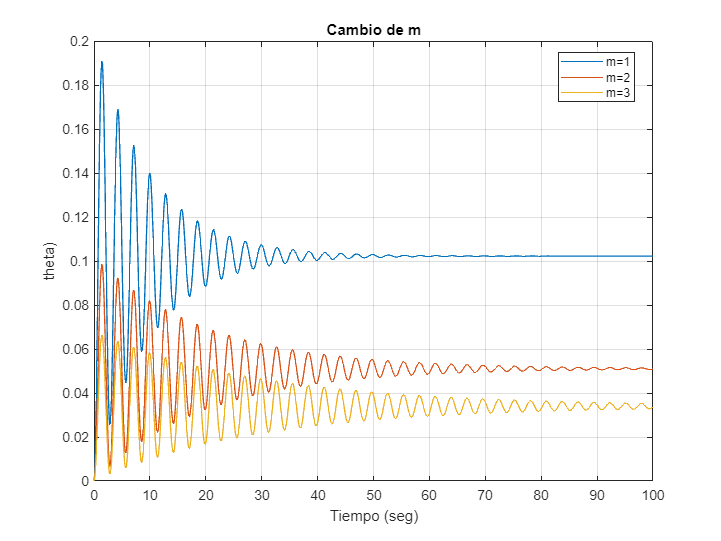

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1:1:3; %Masa en kilogramos
g = 9.8; %Aceleracion de la gravedad
l = 2; %Longitud en metros
F = 0.2; %Fricción viscosa   
U = 1; %Fuerza externa

% Creo las ecuacion de estado para la tasa x1
Tasa_x1 = x2;

% Defino condiciones iniciales:  desde el reposo con angulo cero y velocidad angular cero
Ci_x1 = 0;
Ci_x2 = 0;
% Como vamos a resolver numericamente armamos el vector de condiciones iniciales
Ci = [Ci_x1 Ci_x2];

% Tiempo de muestreo: de 0.1 segundos
Ts = 0.1;
% definimos el tiempo maximo y el minimo
tmin = 0;
tmax = 100;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;

%Graficamos
figure 
for k = 1: length(m) %creamos el vector para la masa
    % Creo las ecuacion de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F/m(k))*x2 + (U/(m(k)*l));

% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);

%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t,Sol6] =  ode45(Funciones_estado,tspan,Ci);
plot(t,Sol6(:,1))
hold on
end
grid on
xlabel('Tiempo (seg)')
ylabel ('theta(t) - Posición angular')
title('Cambio de m')
legend({'m=1','m=2','m=3'}, 'Location', 'best')

## **punto 7**

- Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

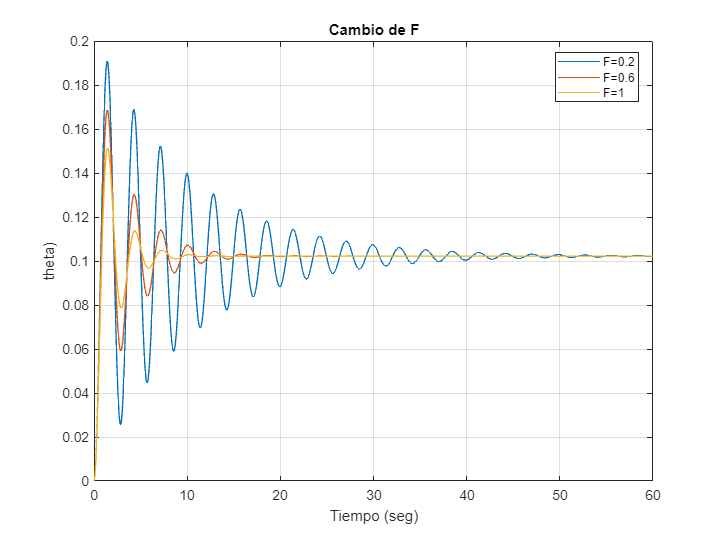

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
g = 9.8; %Aceleracion de la gravedad
l = 2; %Longitud en metros
F = 0.2:0.4:1; %Fricción viscosa  
U = 1; %Fuerza externa

% Creo las ecuacion de estado para la tasa x1
Tasa_x1 = x2;

% Defino condiciones iniciales:  desde el reposo con angulo cero y velocidad angular cero
Ci_x1 = 0;
Ci_x2 = 0;
% Como vamos a resolver numericamente armamos el vector de condiciones iniciales
Ci = [Ci_x1 Ci_x2];

% Tiempo de muestreo: de 0.1 segundos
Ts = 0.1;
% definimos el tiempo maximo y el minimo
tmin = 0;
tmax = 60;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;

%Graficamos
figure 
for k = 1: length(F) %creamos el vector para la fuerza
    % Creo las ecuacion de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F(k)/m)*x2 + (U/(m*l));

% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);

%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t,Sol7] =  ode45(Funciones_estado,tspan,Ci);
plot(t,Sol7(:,1))
hold on
end
grid on
xlabel('Tiempo (seg)')
ylabel ('theta)')
title('Cambio de F')
legend({'F=0.2','F=0.6','F=1'}, 'Location', 'best')

## **punto 8**

Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB                        

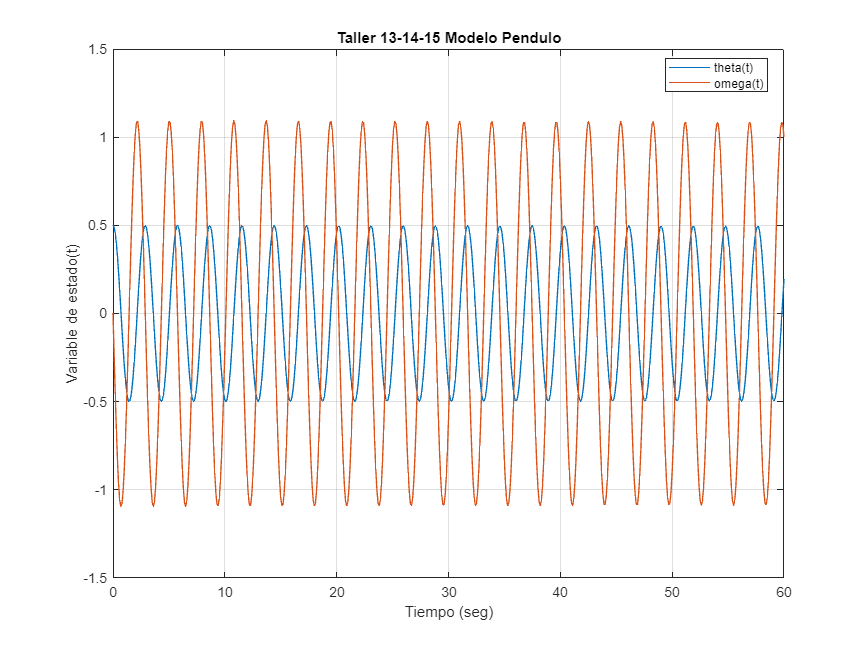

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 1; %Masa en kilogramos
l = 2; %Longitud en metros
g = 9.8; %Aceleracion de la gravedad
F = 0; %Fricción viscosa    
U = 0; %Fuerza externa


% Creo las ecuaciones de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F/m)*x2 + (U/(m*l));
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);


% METODO NUMERICO
% Tiempo de muestreo: de 1 segundo
Ts = 0.1;
% Vamos a trabajar 1 minuto
tmin = 0;
tmax = 60;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;


% Defino condiciones iniciales:  desde el reposo con angulo cero y velocidad angular cero
Ci_x1 = 0.5;
Ci_x2 = 0;
% Como vamos a resolver numericamente armamos el vector de condiciones iniciales
Ci_pendulo = [Ci_x1 Ci_x2];


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t,Sol8] =  ode45(Funciones_estado,tspan,Ci_pendulo);



% Punto 1 Simulamos
% Graficar la solucion
figure
plot(t,Sol8)
grid on
xlabel('Tiempo (seg)')
ylabel ('Variable de estado(t)')
title('Taller 13-14-15 Modelo Pendulo')
legend({'theta(t)','omega(t)'}, 'Location', 'best')

## **punto 9**

- Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

% Defino las variables de estado
syms x1(t) x2(t) % x1 sera el angulo theta. x2 sera la velocidad angular omega

% Defino las constantes:
m = 0.52; %Masa en kilogramos
l = 2; %Longitud en metros
g = 9.8; %Aceleracion de la gravedad
F = 0.61; %Fricción viscosa   
U = 1; %Fuerza externa


% Creo las ecuaciones de estado
Tasa_x1 = x2;
Tasa_x2 = -(g/l)*sin(x1) - (F/m)*x2 + (U/(m*l));
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_x1 Tasa_x2],[x1 x2]);


% METODO NUMERICO
% Tiempo de muestreo: de 1 segundo
Ts = 0.1;
% Vamos a trabajar 1 minuto
tmin = 0;
tmax = 10;
% Construir el vector de tiempo para la solucion
tspan = tmin:Ts:tmax;

t_exp=0:0.4:10;
theta_exp = [ 0 0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.197];
% Defino condiciones iniciales:  desde el reposo con angulo cero y velocidad angular cero
Ci_x1 = 0;
Ci_x2 = 0;
% Como vamos a resolver numericamente armamos el vector de condiciones iniciales
Ci_pendulo = [Ci_x1 Ci_x2];


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t1,Sol1] =  ode45(Funciones_estado,tspan,Ci_pendulo);

% Punto 1 Simulamos
% Graficar la solucion
figure
plot(t1,Sol1(:,1))
grid on
xlabel('Tiempo (seg)')
ylabel ('theta - Posición angular')
title('Punto 9')
legend({'theta(t)','valor aprox'}, 'Location', 'best')

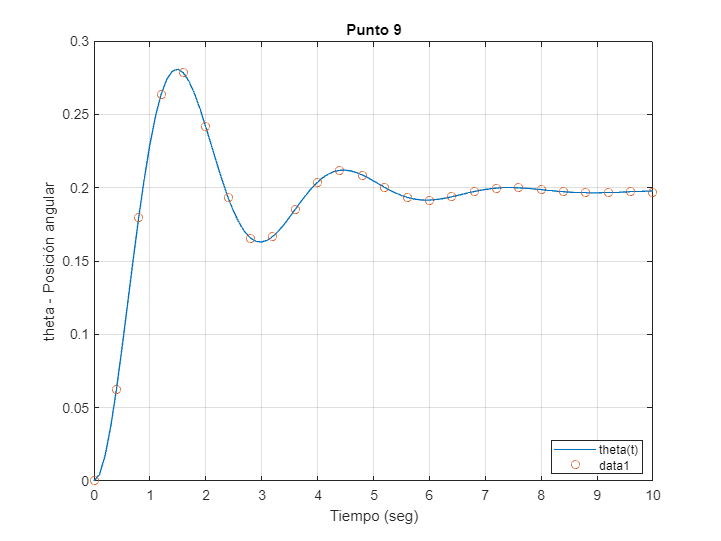

hold on 
plot(t_exp,theta_exp,"o")

## **Punto 10**

Montar un experimento en casa de un péndulo con entrada igual cero y un ángulo inicial entre 20 y 60°, y hallar los parámetros *l* y *f* si se conocen *m* y *g*. Es decir, suponer que no se sabe la longitud. Al final, mostrar la discrepancia de la longitud. ¿Por qué si no hay entrada el experimento no sirve para hallar *f* y *m* como en la tarea anterior?

**Adjunto Link del video del experimento: **[Experimento pendulo simple, Ecuaciones diferenciales - YouTube](https://www.youtube.com/watch?v=EhraoKvgXVM)

**Valores para el experimento:**

**Masa 1: **520.3 g

**Tiempo para llegar al reposos**

- ** ángulo inicial 30**°**:     **11:15 min

- **ángulo inicial  45**°**:     **12:25 min 

-----------------------------------------------------------------------------------------

**Masa 2: **68.9 g

**Tiempo para llegar al reposos**

- ** ángulo inicial 30**°**:**      3:15 min 

- **ángulo inicial  45**°**:    ** 3:52 min 

------------------------------------------------------------------------------------------

**Masa 3: **29.2 g

**Tiempo para llegar al reposos**

- ** ángulo inicial 30**°**:        **3:17 min

- **ángulo inicial  45**°**:        **3:48 min 

**Longitud eje: **85 cm

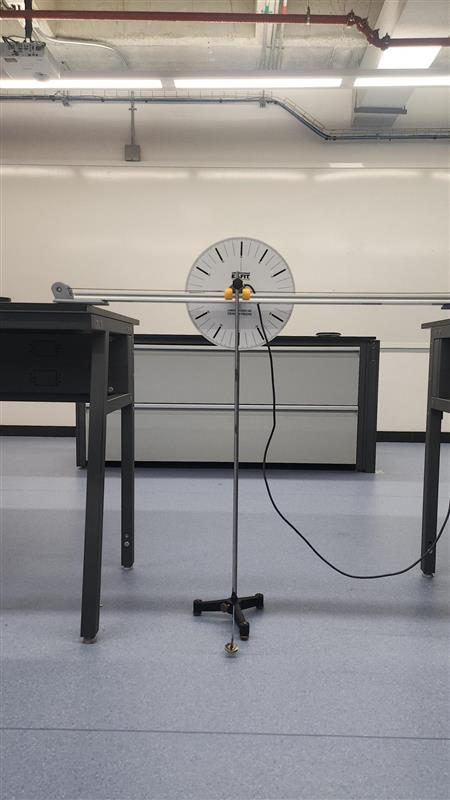

## **Análisis y discusión de los resultados:**

## **punto 1 :**

La gráfica de la ecuación de estado no lineal de un péndulo simple con una fuerza tangencial, en las condiciones especificadas, proporciona una visión interesante de la dinámica del sistema. Este péndulo, con una masa de 1 kg, una longitud de 2 m, una gravedad de 9.8 m/s², un coeficiente de fricción viscosa de 0.2 kg/s y una fuerza externa aplicada tangencialmente de 1 N, muestra un comportamiento dinámico complejo, con oscilaciones que pueden no ser perfectamente periódicas debido a la combinación de fuerzas y restricciones. 

La ecuación de estado no lineal refleja cómo la posición y velocidad del péndulo evolucionan en el tiempo. En este caso, la no linealidad se debe a la fuerza tangencial aplicada, que puede provocar oscilaciones caóticas y no periódicas en el sistema. La presencia de fricción viscosa también juega un papel importante en la amortiguación de las oscilaciones y en la estabilización del sistema, pues se observa que, con el tiempo, la amplitud de las oscilaciones disminuye debido a esta, lo que indica una pérdida gradual de energía en el sistema, hasta alcanzar el estado de equilibrio dinámico.

Dado que el hilo es rígido, la fuerza externa tangencial aplicada genera un momento (o torque) sobre el péndulo. Si este momento producido por la fuerza externa  es lo suficientemente grande como para contrarrestar el efecto del momento causado por la fricción viscosa y la resistencia gravitatoria, el péndulo continuará rotando indefinidamente. En este contexto, la fuerza externa debe superar los 7.5 N para que las gráficas de la velocidad angular y la posición angular en función del tiempo muestren un comportamiento semejante a un movimiento uniforme.

## **punto 2 :**

La tendencia de estabilización evidencia una relación no lineal entre la fuerza externa y la respuesta del péndulo. A medida que la fuerza externa aumenta en el rango de 0 a 7 N con incrementos de 0.5 N, se observa una estabilización de forma gradual. Esto se debe a que el sistema adquiere una mayor capacidad para contrarrestar los efectos de la fricción viscosa y la resistencia gravitatoria, lo que resulta en un péndulo que tiende a mantener una oscilación continua y regular. Este fenómeno sugiere la existencia de un valor crítico de fuerza externa que posibilita al péndulo alcanzar un estado de equilibrio dinámico.

## **punto 3 :**

El retrato de fase proporciona una representación visual de la evolución del sistema en el espacio de estados, considerando un cambio en la condición inicial de la velocidad angular. En este caso, se analizó el comportamiento del péndulo simple con una masa de 1 kg, longitud de 2 m, gravedad de 9.8 m/s², coeficiente de fricción viscosa de 0.2 kg/s y una fuerza externa tangencial de 1 N, asumiendo un hilo rígido.

Al variar la velocidad angular inicial en el intervalo de 3 a 6 rad/s con incrementos de 0.5 rad/s, se pudo observar una diversidad de trayectorias en el espacio de fase, evidenciando notables transformaciones en su forma y estructura. Estos cambios comprenden:

- Ampliación de las órbitas: Con el aumento de la velocidad angular inicial, las órbitas en el retrato de fase tienden a expandirse. Esto señala que el sistema posee una mayor energía cinética inicial, lo que le permite alcanzar ángulos más amplios antes de invertirse o estabilizarse.

- Mayor complejidad: En presencia de velocidades angulares iniciales más elevadas, el sistema puede manifestar un comportamiento más complejo y caótico en el espacio de fase. Esto se manifiesta a través de trayectorias más intrincadas y menos regulares, producto de la interacción entre las fuerzas externas, la fricción viscosa y la gravedad.

- Aumento de la amplitud de las oscilaciones: El incremento en la velocidad angular inicial conlleva a una mayor amplitud en las oscilaciones del péndulo en el espacio de fase. Esto indica que el sistema puede oscilar a mayores distancias de la posición vertical antes de retornar.

##  **punto 4 :**

 La gráfica del retrato de fase para un cambio en la condición inicial de la posición angular en el rango de -6 a 6 rad con incrementos de 0.5 rad, considerando un péndulo simple con una masa de 1 kg, longitud de 2 m, gravedad de 9.8 m/s², coeficiente de fricción viscosa de 0.2 kg/s y una fuerza externa aplicada tangencialmente de 1 N en un hilo rígido, nos permite observar cómo diferentes condiciones iniciales de la posición angular influyen en el comportamiento del péndulo. Los resultados resaltan los siguientes puntos:

-  Diversidad de trayectorias: A medida que la posición angular inicial varía, se pueden identificar diferentes trayectorias en el retrato de fase. Esto indica que el sistema puede seguir caminos distintos en el espacio de fase según la condición inicial, lo cual es característico de sistemas no lineales.

-  Puntos de equilibrio y órbitas: Dependiendo de la posición angular inicial, se pueden identificar puntos en el espacio de fase donde el sistema se encuentra en equilibrio, en este caso son 3. También se observan órbitas que representan las posibles evoluciones del sistema en el tiempo. 

- Comportamiento caótico: En algunos casos, especialmente con condiciones iniciales cercanas a valores críticos, se pueden observar regiones en el retrato de fase que indican un comportamiento caótico. Esto se manifiesta en trayectorias aparentemente desordenadas y no periódicas.

##  **punto 5 :**

El cambio en la longitud del péndulo tiene un efecto significativo en el desplazamiento angular (θ) del sistema. Para analizar este efecto, consideramos un péndulo con una masa de 1 kg, una fuerza externa de 1 N, gravedad de 9.8 m/s², coeficiente de fricción viscosa de 0.2 kg/s y condiciones iniciales con posición y velocidad angular inicial igual a cero. 

- Mayor Longitud -> Mayor Desplazamiento Angular: Cuando la longitud del péndulo aumenta, el desplazamiento angular también tiende a aumentar. Es decir, el péndulo alcanzará ángulos más grandes en relación a la posición vertical antes de invertirse y volver a oscilar en la dirección opuesta.

- Mayor Momento de Inercia: Una mayor longitud implica que la masa está ubicada a una mayor distancia del punto de pivote. Esto aumenta el momento de inercia del sistema. El momento de inercia es una medida de la resistencia de un objeto a cambiar su estado de movimiento rotacional, y en este caso, está relacionado con la amplitud de las oscilaciones.

- Frecuencia de Oscilación Disminuida: Una longitud mayor disminuye la frecuencia natural de oscilación del péndulo. La frecuencia se refiere a la cantidad de oscilaciones que realiza el péndulo en un período de tiempo determinado. Una mayor longitud implica un mayor período y, por lo tanto, una menor frecuencia. 

- Menor Sensibilidad a Fuerzas Externas: Péndulos con longitudes mayores tienden a ser menos sensibles a fuerzas externas o perturbaciones. Esto significa que es más difícil alterar el movimiento del péndulo cuando tiene una longitud mayor.

##  **punto 6 :**

El cambio en la masa del péndulo tiene un efecto importante en el desplazamiento angular del sistema; se considera una fuerza externa constante de 1 N y condiciones iniciales donde posición y la velocidad angular inicial son cero. 

- Mayor Masa -> Mayor Desplazamiento Angular: Aumentar la masa del péndulo incrementa el desplazamiento angular. Esto significa que el péndulo alcanzará ángulos más grandes en relación a la posición vertical antes de invertirse y volver a oscilar en la dirección opuesta. 

- Mayor Momento de Inercia: Una mayor masa significa más materia concentrada en el extremo del péndulo. Esto resulta en un aumento en el momento de inercia del sistema, lo que a su vez contribuye a un mayor desplazamiento angular. 

- Mayor Fuerza Gravitatoria: Una masa más grande implica una fuerza gravitatoria mayor actuando sobre el péndulo. Esto significa que el péndulo experimentará una mayor aceleración hacia la posición de equilibrio después de ser desplazado. 

- Mayor Inercia al Cambio de Movimiento: Una mayor masa hace que el péndulo sea más resistente a cambios en su estado de movimiento. Esto significa que se requerirá más energía para alterar su trayectoria, lo que se traduce en oscilaciones más amplias. 

- Fuerza Externa Constante: Dado que la fuerza externa es constante, no varía con la masa del péndulo. Por lo tanto, cualquier cambio en el desplazamiento angular se debe principalmente a las propiedades de inercia y gravedad relacionadas con la masa

##  **punto 7 : **

El cambio en el coeficiente de fricción viscosa del péndulo tiene un gran efecto en el desplazamiento angular del sistema; se considera una fuerza externa constante de 1 N y condiciones iniciales donde posición y la velocidad angular inicial son cero.

- Mayor Coeficiente de Fricción Viscosa -> Menor Desplazamiento Angular: Aumentar el coeficiente de fricción viscosa del péndulo tiende a disminuir el desplazamiento angular. Esto significa que el péndulo alcanzará ángulos más pequeños en relación a la posición vertical antes de invertirse y volver a oscilar en la dirección opuesta.

- Mayor Resistencia al Movimiento: Un mayor coeficiente de fricción viscosa genera una mayor resistencia al movimiento del péndulo. Esto disipa más energía del sistema a medida que se mueve, lo que resulta en una amplitud de oscilación reducida.

- Disipación de Energía: La fricción viscosa convierte parte de la energía cinética del péndulo en calor a medida que se mueve. Esto tiene un efecto amortiguador en las oscilaciones, lo que significa que el péndulo se detendrá más rápido y no alcanzará ángulos tan grandes.

- Tiempo de Estabilización Más Rápido: Con un mayor coeficiente de fricción viscosa, el péndulo se estabilizará más rápido y alcanzará su posición de equilibrio más rápidamente después de ser desplazado.

- Menor Sensibilidad a Perturbaciones: La fricción viscosa también reduce la sensibilidad del sistema a pequeñas perturbaciones o fuerzas externas, lo que significa que es menos probable que se vea afectado por influencias externas.

##  **punto 8 :** 

Dado que estamos considerando un movimiento libre no amortiguado (f = 0, u = 0) y que la posición angular inicial ω(0) es menor a 0.5 radianes, podemos utilizar la aproximación  sin (θ) $\approx$ θ para ángulos pequeños.

La ecuación de estado para el sistema sería:

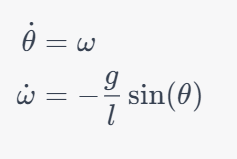

Utilizando la aproximación lineal para el seno, la ecuación de estado se convierte en:

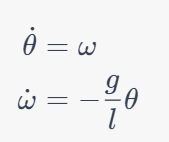Esta es una ecuación diferencial lineal de segundo orden con coeficientes constantes.

Para convertirla en una ecuación diferencial homogénea con coeficientes constantes, introducimos una nueva variable $x$ tal que $x$ = θ, y expresamos la segunda derivada de θ en términos de $x$  y sus derivadas. Así obtenemos:

Esta es una ecuación diferencial homogénea de segundo orden con coeficientes constantes.

La solución general para esta ecuación es de la forma:

 Donde $A$ y $B$  son constantes determinadas por las condiciones iniciales.

Para medir la aceleración de la gravedad si se conoce la longitud, se puede utilizar un péndulo simple y medir el periodo de oscilación $T$ . La relación entre el periodo de oscilación y la longitud del péndulo es:

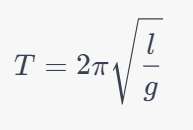

- Despejando la aceleración de la gravedad g obtenemos:

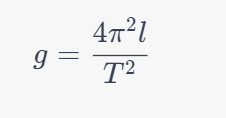

- Para obtener la longitud si se conoce la aceleración de la gravedad, se puede usar la misma fórmula y despejar la longitud $l$ :

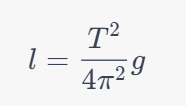

En resumen, cuando se considera un péndulo simple con condiciones específicas (movimiento libre no amortiguado, posición angular inicial pequeña y aproximación lineal del seno), se puede derivar una ecuación de estado lineal con coeficientes constantes. Esta ecuación describe el comportamiento del sistema en función del tiempo.

Además, se estableció cómo medir la aceleración de la gravedad si se conoce la longitud del péndulo, y viceversa. Utilizando la relación entre el periodo de oscilación y la longitud, es posible determinar la aceleración de la gravedad experimentalmente. Del mismo modo, con la aceleración de la gravedad conocida, se puede calcular la longitud del péndulo.

Estos métodos proporcionan herramientas prácticas para investigar y comprender el comportamiento de un péndulo simple en situaciones específicas, lo que resulta útil en numerosas aplicaciones físicas y experimentos.

## **punto 9 :** 

Para aproximar los valores de f (coeficiente de fricción viscosa) y m (masa del péndulo) dados la respuesta temporal de un péndulo con fuerza externa de 1 N, longitud igual a metros y gravedad  de 9.8 m/s², se puede seguir el siguiente procedimiento:

1. **Examinar la Respuesta Temporal: **Se debe analizar la representación gráfica o los datos que muestran la evolución del sistema a lo largo del tiempo. Esto incluye observar la amplitud de las oscilaciones y cómo disminuye la amplitud con el tiempo debido a la fricción.

2.** Identificar Pautas y Relaciones: **Se buscarán correlaciones entre la respuesta temporal y los parámetros  f y m. Por ejemplo, una rápida disminución en la amplitud podría indicar una alta  fricción viscosa. Si las oscilaciones persisten por más tiempo, podría sugerir una baja  fricción viscosa.

3. **Aproximar f y m mediante Tanteo:**

-    Prueba con Diferentes Valores de f y m:  Se seleccionarán valores iniciales estimados para f y m  y se utilizarán en un modelo del péndulo para simular su comportamiento. Por ejemplo, se podría comenzar con (f = 0.1) y observar cómo se compara la respuesta simulada con la respuesta temporal registrada.

-    Ajustes Iterativos: A partir de los resultados obtenidos, se realizarán ajustes iterativos en los valores de  f y m hasta que la respuesta simulada se aproxime de manera satisfactoria a la respuesta temporal real. En este caso los valores que más se aproximan a la respuesta son  f= 0.61N y m = 0.52kg

4. **Evaluar la Precisión:** La precisión de los valores de  f y m se evaluará comparando la respuesta simulada con la respuesta temporal medida. Si coinciden de manera adecuada, se habrán aproximado correctamente  f y m.

5. **Refinar los Valores si es Necesario: **Si los resultados no son satisfactorios, se puede repetir el proceso con diferentes valores de  f y m hasta obtener una concordancia óptima entre la respuesta simulada y la temporal.

## **punto 10 :**

 El experimento realizado consistió en observar el comportamiento de péndulos de diferentes masas, iniciados desde ángulos iniciales de 30° y 45°, hasta llegar a un estado de reposo. A continuación, se presenta un análisis de los resultados obtenidos:

**1. Péndulo con Masa 1 (520.3 g):**

   - Tiempo para llegar al reposo con ángulo inicial de 30°: 11 minutos y 15 segundos.

   - Tiempo para llegar al reposo con ángulo inicial de 45°: 12 minutos y 25 segundos.

  ** Comentario: **Se observa que el péndulo con mayor masa requiere más tiempo para alcanzar el reposo desde ambas posiciones iniciales. Esto sugiere que la mayor masa impone una mayor inercia al sistema, lo que afecta la rapidez con la que el péndulo se detiene.

**2. Péndulo con Masa 2 (68.9 g):**

   - Tiempo para llegar al reposo con ángulo inicial de 30°: 3 minutos y 15 segundos.

   - Tiempo para llegar al reposo con ángulo inicial de 45°: 3 minutos y 52 segundos.

**Comentario: **En este caso, el péndulo con menor masa demuestra una mayor rapidez en llegar al reposo desde ambas posiciones iniciales. Esto indica que la menor masa implica una menor inercia, lo que permite al sistema detenerse más rápidamente.

**3. Péndulo con Masa 3 (29.2 g):**

   - Tiempo para llegar al reposo con ángulo inicial de 30°: 3 minutos y 17 segundos.

   - Tiempo para llegar al reposo con ángulo inicial de 45°: 3 minutos y 48 segundos.

   **Comentario:** El péndulo con la masa más baja muestra resultados similares al péndulo con Masa 2, lo que confirma la relación inversa entre masa e inercia.

**Influencia del ángulo en el tiempo para llegar al reposo:**

Además, Para los tres casos se detectaron diferencias notables en el tiempo requerido para el reposo al variar el ángulo inicial. En general, los péndulos iniciados desde 45° necesitaron más tiempo para detenerse que aquellos iniciados desde 30°. Esto sugiere que un mayor ángulo inicial implica una mayor energía cinética inicial y, por lo tanto, más tiempo para disipar esa energía y llegar al reposo.

#### **En conclusión:**

Los resultados del experimento indican que tanto la masa como el ángulo inicial del péndulo influyen en el tiempo necesario para que el sistema alcance el estado de reposo. Péndulos con mayor masa y ángulos iniciales más amplios tienen una mayor inercia y por lo tanto, tardan más tiempo en detenerse. Por otro lado, péndulos con menor masa y ángulos iniciales más pequeños tienen una menor inercia y se detienen más rápidamente